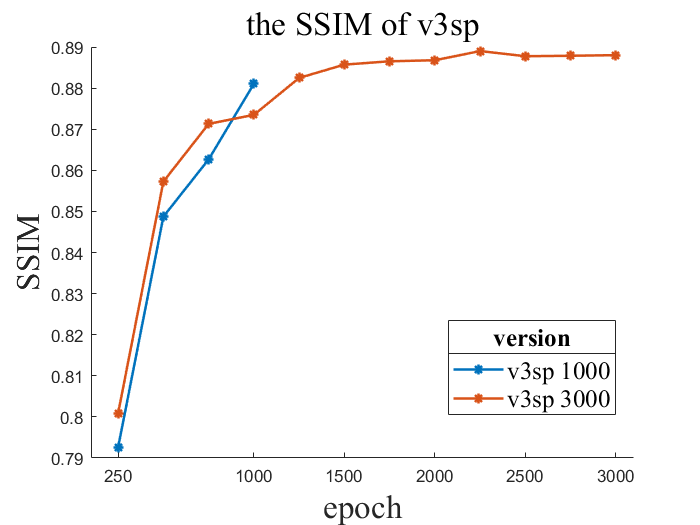

clc; clear;

figure;
metric = 'SSIM';
hold on;

version = ["v3sp_1000", "v3sp_3000"];

% , "v3p_1000"

for i = 1:length(version)
    add_plot(metric, version(i));
end

% 设置图片各项属性
key = {'FontSize', 'FontName'};
value = {20, 'Times New Roman'};

% title_name  = "Comparison of versions on " + metric;
title_name = "the " + metric + " of v3sp";
title(title_name, 'FontSize', 20, 'FontName', 'Times New Roman');

xlb = xlabel("epoch");
ylb = ylabel(metric);

version = strrep(version, '_', " ");
leg = legend(version);
set([xlb, ylb, leg], key, value);
set(leg, "FontSize", 15, 'Position', [0.66, 0.25, 0.2, 0.1]);
title(leg, "version", 'FontSize', 15, 'FontName', 'Times New Roman');

xlim([100, 3100]);
ax = gca;
ax.XTick = [250, 1000:500:3000];

% axis square;